clear
close all
load CMI_data.mat
whos

  Name        Size               Bytes  Class     Attributes

  CMI         1x1             60481176  struct              
  readme      1x68                 136  char                



The data are contained in the structure CMI, with t being datenum time, and p the pressure sensor data, in units of equivalent water depth in meters, at the four sites (2,3,6, and 7) across the fringing reef. The data consists of 1-second measurements collected in 5400 sec bursts every 3 hours (i.e., 1.5 hours on, 1.5  hours off). There are 200 bursts.

For each of the four sites using CMI.p*, compute SS significant wave heights (Hss) (frequencies > 1/25 Hz) and IG significant wave heights (Hig) (1/900 Hz <= frequencies  <= 1/25 Hz) for each burst. 

For site 7, use CMI.e7 (surface-corrected pressure) instead of CMI.p7. 

**Plot the Hss (Figure 1) and Hig (Figure 2) time series. **

for site = 1:4
    if site == 1
        data = CMI.p2;
    elseif site == 2
        data = CMI.p3; 
    elseif site == 3
        data = CMI.p6; 
    else
        data = CMI.e7; 
    end
    
  
    for burst = 1:200
        x = data(:,burst); % Extract burst
        Hs(burst, site) = 4 * std(x); 
        
        % FFT calculations
        X=fft(detrend(x,2));
        N = length(x); 
        dt = 1; 
        f=(-N/2:N/2-1)/(N*dt);
        Xshift = fftshift(X,1);
        
        % Compute variance using FFT
        var_x = 1 / ((N - 1) * N) * sum(abs(X).^2);
        
        % Compute Sea-Swell Significant Wave Height (Hss)
        kss = find(abs(f) > 1/25); 
        Hss(burst, site) = 4 * sqrt(1 / ((N - 1) * N) * sum(abs(Xshift(kss)).^2));
        
        % Compute Infragravity Significant Wave Height (Hig)
        kig = find(abs(f) >= 1/900 & abs(f) <= 1/25); 
        Hig(burst, site) = 4 * sqrt(1 / ((N - 1) * N) * sum(abs(Xshift(kig)).^2));
    end
end

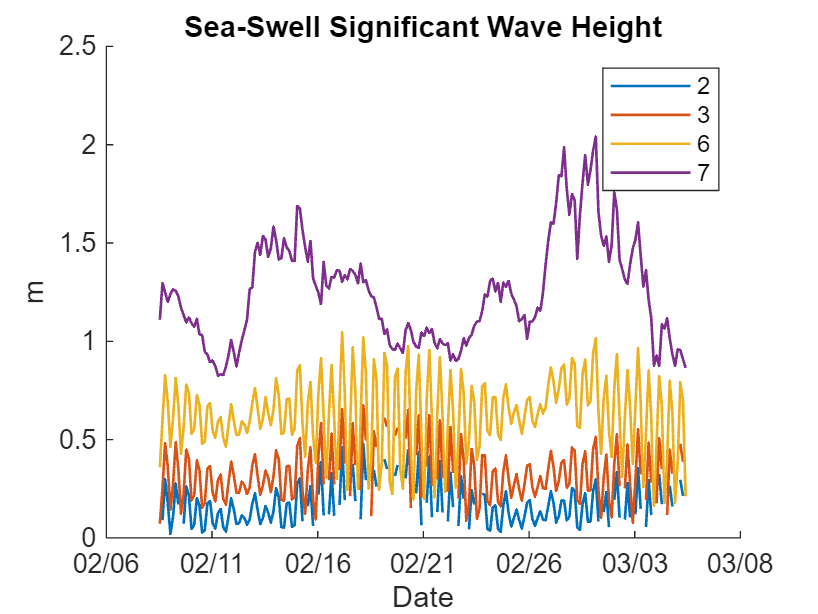

figure(1);
t_mean=mean(CMI.t);
hold on;
plot(t_mean, Hss(:, 1), 'DisplayName', '2', 'LineWidth', 1);
plot(t_mean, Hss(:, 2), 'DisplayName', '3', 'LineWidth', 1);
plot(t_mean, Hss(:, 3), 'DisplayName', '6', 'LineWidth', 1);
plot(t_mean, Hss(:, 4), 'DisplayName', '7', 'LineWidth', 1);
hold off;
title('Sea-Swell Significant Wave Height');
xlabel('Date');
ylabel('m');
legend('2','3','6','7');
datetick('x', 'mm/dd', 'keepticks');

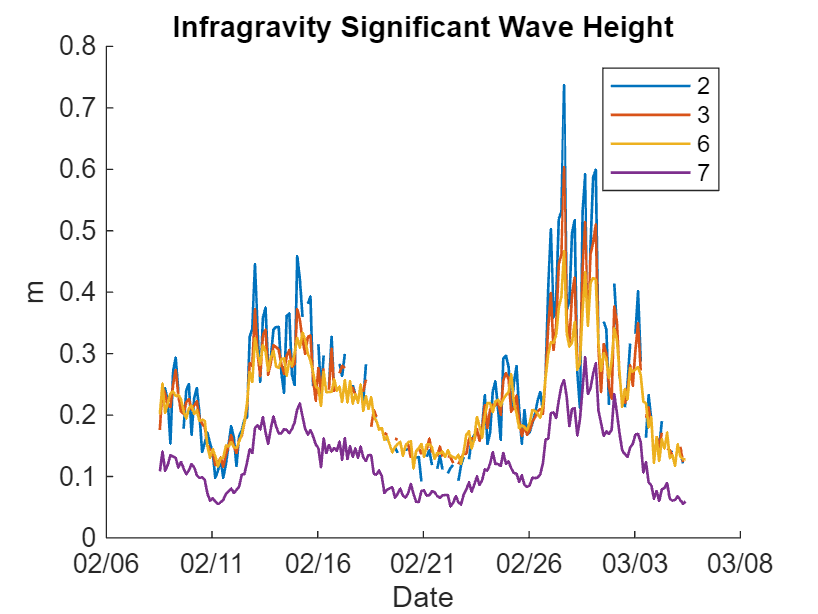

figure(2);
t_mean=mean(CMI.t);
hold on;
plot(t_mean, Hig(:, 1), 'DisplayName', '2', 'LineWidth', 1);
plot(t_mean, Hig(:, 2), 'DisplayName', '3', 'LineWidth', 1);
plot(t_mean, Hig(:, 3), 'DisplayName', '6', 'LineWidth', 1);
plot(t_mean, Hig(:, 4), 'DisplayName', '7', 'LineWidth', 1);
hold off;
title('Infragravity Significant Wave Height');
xlabel('Date');
ylabel('m');
legend('2','3','6','7');
datetick('x', 'mm/dd', 'keepticks'); 

**How do Hss and Hig vary in amplitude across the reef?**

Hss shows the highest amplitudes at site 7, indicating that the forereef experiences the greatest sea-swell (SS) wave energy. Hss decreases in amplitude as waves propagate across the reef (site 7 →6 → 3 → 2). Additionally, the variation of movements in amplitude across the reef reduces: Site 7 shows the greatest amplitude variation, followed by site 6, and then site 3, with site 2 exhibiting the least variation.

In contrast, Hig demonstrates an opposite pattern compared to Hss. The highest amplitudes are observed at site 2, indicating that the inner reef flat experiences the greatest infragravity (IG) wave energy. Hig decreases in the amplitude across the reefs (site 2 →3 → 6 → 7), indicating that IG waves are less effectively dissipated by the reef.

**Compute the burst-averaged water depth at p7 as a proxy for the tidal height. Plot the time series with the mean removed (Figure 3).**

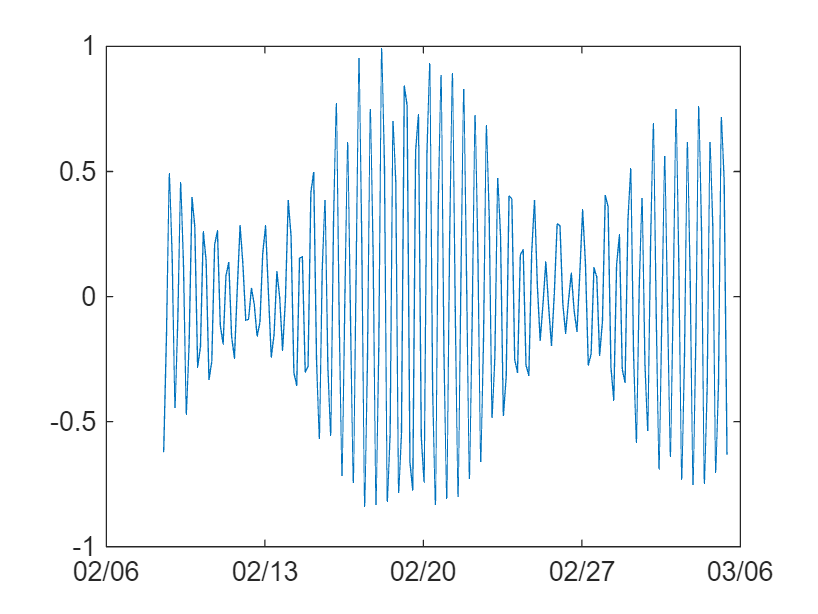

figure(3);
plot(t_mean,detrend(mean(CMI.p7)))
datetick

**For the wave burst with maximum Hss at sensor 7, plot the autospectrum for sensors 2, 3, 6, and 7 (Figure 4). **Use the function auto_spc.m in the Module 4 folder.

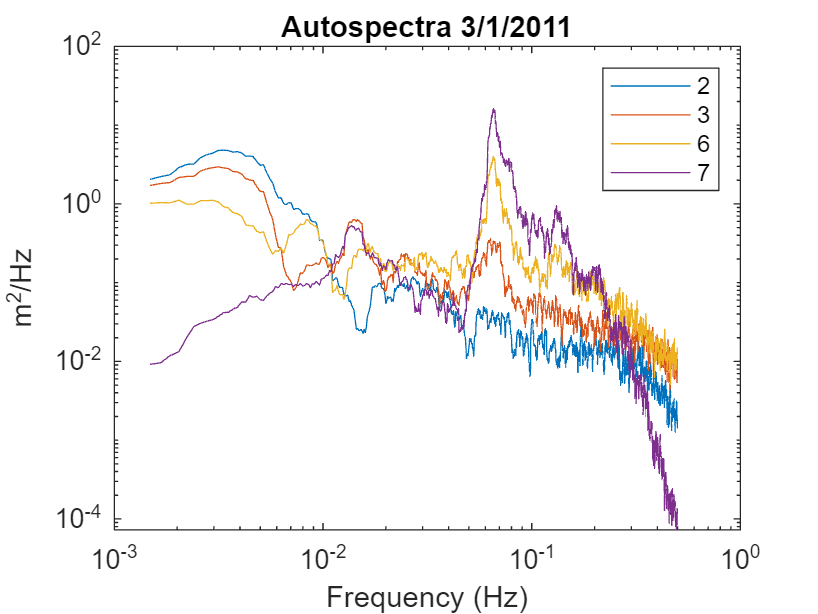

data = CMI.p7; 
[m, n] = size(data); 
[S1, f] = auto_spc(data(:,1), 1, 15); % Compute autospectrum for first column
S = NaN(length(S1), n); % Initialize autospectrum matrix

% Compute the autospectrum for each wave burst
for j = 1:n
    [S(:,j), f] = auto_spc(data(:,j), 1, 15);
end

% Calculate Hss for each wave burst
Hss = NaN(1, n);
df = f(2) - f(1); 
for j = 1:n
    Hss(j) = 4 * sqrt(sum(S(:,j) * df)); 
end

% Find the wave burst with the maximum Hss
[maxHss, maxIndex] = max(Hss);
[S2, f] = auto_spc(detrend(CMI.p2(:, maxIndex), 2), 1, 15);
[S3, f] = auto_spc(detrend(CMI.p3(:, maxIndex), 2), 1, 15);
[S6, f] = auto_spc(detrend(CMI.p6(:, maxIndex), 2), 1, 15);
[S7, f] = auto_spc(detrend(CMI.p7(:, maxIndex), 2), 1, 15); 

figure(4);
loglog(f, S2, f, S3, f, S6, f, S7);
legend('2', '3', '6', '7');
xlabel('Frequency (Hz)');
ylabel('m^2/Hz');
title('Autospectra 3/1/2011')